clc
clear all

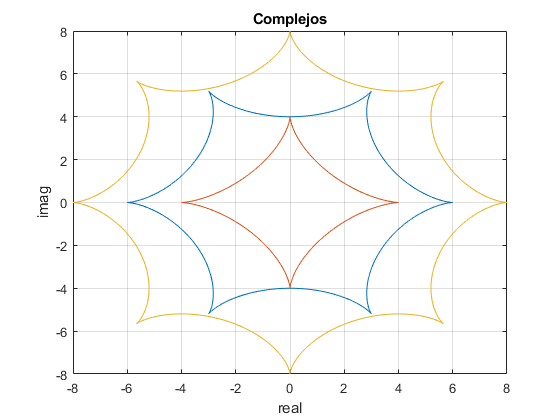

%=====Hipocicloides=====

%Ecuaciones de los hipocicloides
fx = @(r1,r2,alpha) (r1-r2)*cos(alpha)+r2*cos(alpha*(1-(r1/r2)));
fy = @(r1,r2,alpha) (r1-r2)*sin(alpha)+r2*sin(alpha*(1-(r1/r2)));

a = 0:0.01:2*pi;

%Se evaluan en diferentes k 
fxx6 = fx(6,1,a);
fyy6 = fy(6,1,a);
fxx4 = fx(4,1,a);
fyy4 = fy(4,1,a);
fxx3 = fx(8,1,a);
fyy3 = fy(8,1,a);

%Plot de los hipocicloides en el plano complejo
plot(fxx6,fyy6);
grid on
title('Complejos')
xlabel('real')
ylabel('imag')
hold on
plot(fxx4,fyy4)
hold on
plot(fxx3,fyy3)
hold off

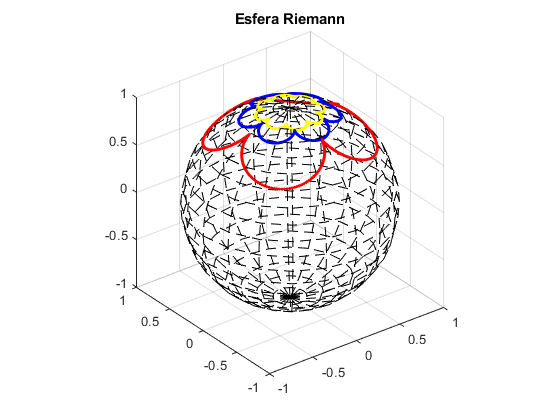


%Cambio a coordenadas de Riemann y plot en la esfera
f_plot_coord_riemann(fxx6+1i*fyy6,"b");
hold on
f_plot_coord_riemann(fxx4+1i*fyy4,"r");
hold on
f_plot_coord_riemann(fxx3+1i*fyy3,'y');
title('Esfera Riemann');
hold off